# Introduction to System Identification

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India    

## Introduction

As seen earlier, implementation of MPC needs a good model for prediction of the future plant behavior. The dynamical plants are typically described by mechanistic model comprising of differential equations, which are nonlinear in nature. To simplify the control design and analysis a linear perturbation model is used, which may be obtained by linearizing the nonlinear dynamical model ([Linearization of Nonlinear Models](matlab:open('../3. Linearized Models for MPC Formulation/L01_From Dynamic Model to Predictive Optimal Control.mlx'))). 

Development of linear state space/transfer function models starting from first principles/grey box models is impractical proposition in many situations. For very complex and large dimensional systems, the physics of the system is usually not understood sufficiently well to be able to quantify system dynamic behaviour accurately.  As a consequence, a reliable mechanistic nonlinear model may not be readily available for the system under consideration that can provide accurate dynamic predictions. A practical alternative is to directly develop a linear perturbation model using operating data collected from the system. Surprisingly, developing such models is comparatively easy and less time consuming. 

In this module we will see how such a data-driven linear perturbation model can be obtained. In  system theory, such an exercise is called **System Identification** and is an integral part of any model based control software. We will learn how to design an experiment to obtain data from the plant that will enable us to identify a good quality data-driven model. We will also see how different forms of models can be directly obtained from experimental data.  

Identification of such data-drive models typically requires 4-steps:  

- Design inputs to query plant behavior (**Design of Experiments**)

- Inject input perturbations into the plant and record measured outputs generated in response  to the perturbations (**Experimental Data Collection**)

- Select an appropriate model structure for capturing system dynamics (**Model Structure Selection**)

- Use data to estimate parameters of the chosen dynamic model (**Parameter Estimation**)

In this lesson, we will see how to obtain the experimental data for obtaining the data based models. 

**Learning Objectives:**

To understand the basics of acquiring experimental data required for system identification.

## Generating Experimental Data for Data Driven Models 

Accuracy of such models is highly dependent on the quality of available data. At times, reliable sensors may not be available, resulting in poor/inaccurate measurements that show high variability. Moreover the measurements obtained using electronic transmitters are corrupted with random fluctuations (or measurement noise). The process of acquiring data needed for data-driven models is depicted in Figure 1. As shown in Figure 1, the process is affected due to measurement noise as well as unmeasured disturbances, which renders the task of model identification difficult.

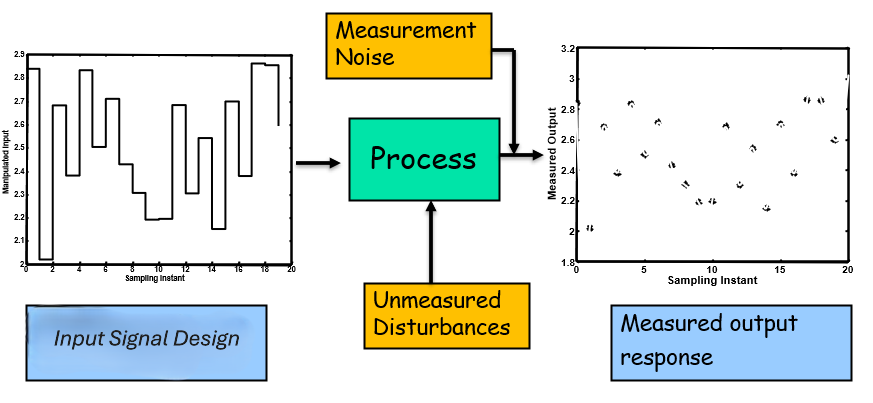

**Figure 1:**  **Data Driven Modelling**

- Measurements are inaccurate due to poor quality sensors or degradation of sensors 

- Process is influenced by unknown disturbances, which may arise from internal factors, such as process parameter drifts, as well as external factors like fluctuations in input conditions or power fluctuations 

- Inherent to any model development exercise are errors committed due to approximations that arise from modeling assumptions 

- Quality of data-driven models is influenced by factors like data size or volume and data quality (whether the injected perturbations sufficiently excite dominant dynamic modes of the system)

### Excitation Inputs  

Various forms of input signals are injected into the plant to characterize a system's behavior, including step, sinusoidal, chirp, and pseudo-random signals. The choice of the input signals that can effectively excite the system help in revealing dynamics of the system. These inputs can be generated using a computer program, and then applied to the process typically under the open loop conditions. The output signals are collected using sensor-transmitter and Analog to Digital Converter systems. **Data Acquisition **is an important aspect of system identification. 

Two types of inputs signals are predominantly used for data generation:

- **Step Inputs**: A positive or negative step change is introduced in one input at a time while holding other inputs constant. Data generated using this type of input is useful for model structure selection. For example, if the step response with respect to certain manipulated input shows oscillatory behavior, then we know that the Laplace transfer function model for the system must have denominator polynomial of at least second order and with two complex conjugate poles. Moreover, the step responses allow us to find signs of the steady state gains. However, step tests need to be conducted sequentially and this can results in long time for experimentation. Moreover, measured and unmeasured disturbances may not remain constant during the step test.  

- **Random Binary Signal (RBS) Inputs: **This type of signal consists of sequences of positive and negative steps changes injected simultaneously in multiple or all manipulated inputs. This ensures that the output remains in the neighborhood of the operating point. As an illustration, consider  the quadruple tank experimental setup at Automation Lab, Chemical Engineering, IIT Bombay shown in Figure 2. Figure 3 shows schematic representation of inputs and outputs associated with the experimental setup. A typical input and output data collected from by injecting RBS input is shown in Figures 4 and 5, respectively. Such type of input excitation can reduce time required for data collection. The resulting output data, however, does not provide any clue to model structure.

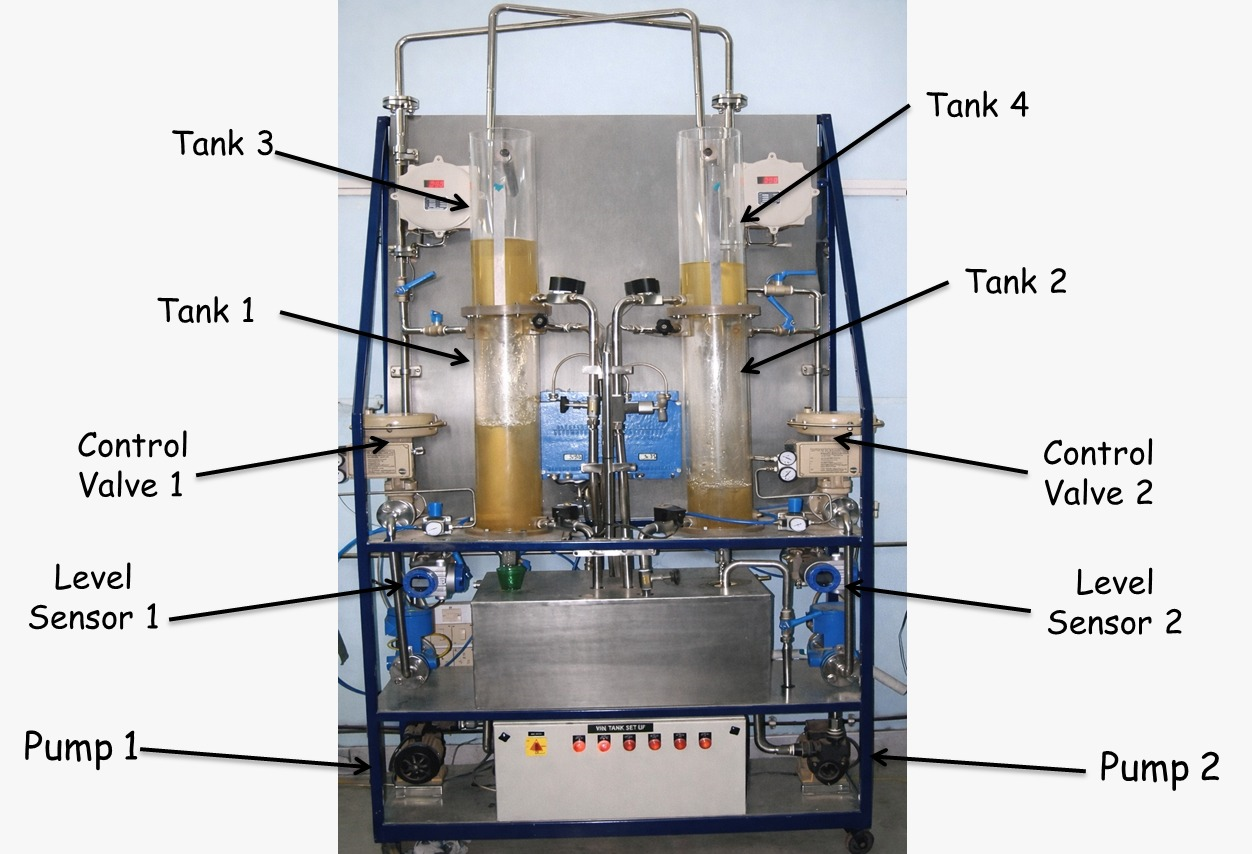

**Figure 2: ** **Quadruple Tank Experimental setup at Automation Lab, Chemical Engineering, IIT Bombay**

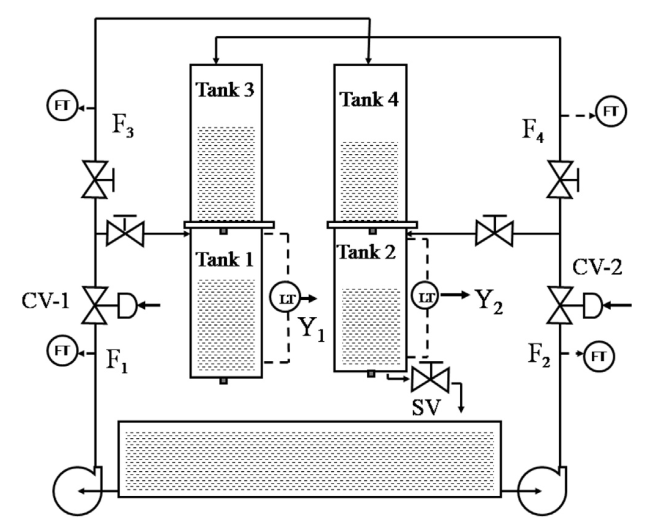

**Figure 3: Quadruple Tank Experimental Setup - Schematic Representation of inputs and outputs**

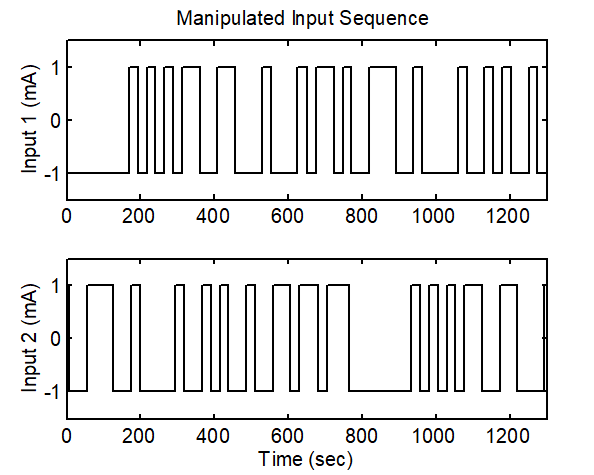

**Figure 4: Perturbation in Manipulated Inputs *****u*****(*****k*****) for Q-Tank Experimental set up**

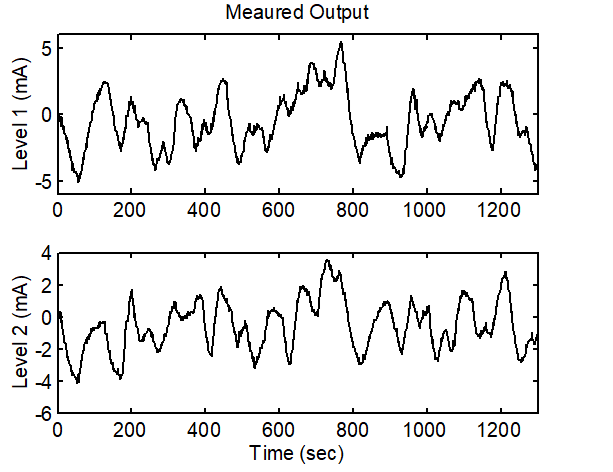

**Figure 5: Perturbation in Measured Outputs y(*****k*****) for Q-Tank Experimental set up**

### Splitting Data for Model Identification and Validation

It is important that the model so obtained fits the data. It is obvious that the model obtained from a particular data set will fit that data set well. But it should also follow the plant behaviour at the data at same operating conditions, but different time instants. Hence the data obtained from the experiments is split as follows 

- For model identification (Getting the model or fitting the model) and

- Validation (Verification of the model).

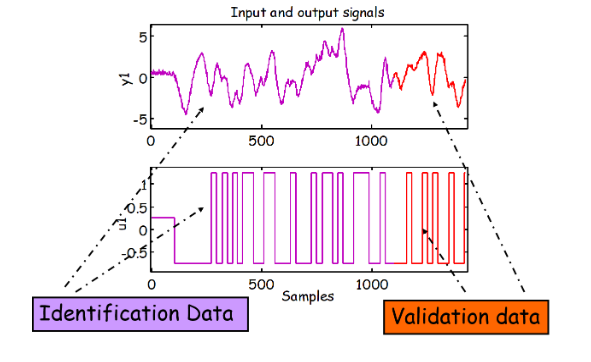

**Figure 6: Input Output Perturbation Data for Identification and Validation**

## Quadruple Tank Simulation for Data Generation 

To develop model from experimental data, we need access to an experimental setup. Moreover, subsequent to model identification from experimental data, we need to go back and implement the identified model based controller. However, to introduce the fundamentals of data generation and model identification, we treat of the mechanistic model based simulator of the Quadruple Tank system as the "***experimental setup***". The grey-box or black-box model identified using the "***experimental data***" generated from this setup will then be used for control of this experimental setup. Thus, only for the data generation step, we assume that a mechanistic model based process simulator is available with us and is treated as the ***experimental setup***. 

- Design a manipulated Input sequence  $U_N \equiv \{{U(0),U(1),.....,U(N)}\}$ in the neighborhood of $\bar{U}$

- Inject the designed input sequence while the system is operating in the in the neighborhood of Steady State Operating Point,$\left(\bar{Y} ,\bar{U} \right)$ and collect measured output data, $Y_N\equiv \{{Y(0),Y(1),.....,Y(N)}\} $,  generated in response to the injected input perturbations

- Generate Perturbation Variables Data set 

- Measured Outputs $y_N\equiv {y(0),y(1),.....,y(N)}$ and

- Known and/or Manipulated Inputs   $u_N\equiv {u(0),u(1),.....,u(N)}$ such that

                                                     $\;y\left(k\right)=Y\left(k\right)-\bar{Y}$-----------(1)

                                                     $u\left(k\right)=U\left(k\right)-\bar{U}$----------(2)

We simulate the Q-Tank system for a RBS input using model parameters given in [module 3](matlab:open('../2. Dynamic_Model_To_Moving_Horizon_Optimal_Control/L02_Linearization_of_Noninear_Dynamic_Models.mlx')) and sampling interval of 4 seconds. 

close all % close all open figures 
clear all % clear work space 

global QTank U_k D_k % Define global variables 

**Task 1:** Select operating point: **(1) Minimum Phase Operation (2) Non-minimum phase operation. **This will load the parameters specific to the operating point. Let us set the operating point to Minimum Phase

operating_pt=1; 
if operating_pt==1
    load QTank_MinPhase_Model
else
    load QTank_NonMinPhase_Model
end

**Task 2:** Select number of samples in the simulation. This will be useful in creating vectors of length equal to N for storing the simulation data.

N=2047;
samp_T =QTank.samp_T ; % Sampling interval 
n_st = length( QTank.Xs ) ; % No. of states 
n_op = length( QTank.Ys ) ; % No. of measured o/p 
n_ip = length( QTank.Us ) ; % No. of man. inputs 
n_ud = n_ip ; 
n_ud = n_ip ; 
 QTank.dk_sigma=0.02;
% Generate measurement noise sequence
vk = mvnrnd(zeros(n_op,1), QTank.R_mat ,N) ; 
vk = vk' ; 
% Generate state noise sequence 
QTank.Q_mat=QTank.Q_mat*eye(n_op);
wk = mvnrnd(zeros(n_op,1), QTank.Q_mat, N) ; 
wk = wk' ;
% Create matrices for saving original variables 
Xk = zeros(n_st, N) ; 
Uk = zeros(n_ip, N) ; 
Yk = zeros(n_op, N) ;
% Create Matrices for saving perturbation variables
xk = zeros(n_st, N) ; 
uk = zeros(n_ip, N) ; 
yk = zeros(n_op, N) ;

### **Generation of Identification Data**

The **System identification Toolbox** in **MATLAB** has a library of functions to aid system identification exercise. 

####  Inputs for Identification

We use the command [**idinput **](https://in.mathworks.com/help/ident/ref/idinput.html)to generate the user-defined input signal needed to perturb the plant for generation of the input-output data for identification.

    U = idinput(N,TYPE,BAND,LEVELS)

    U: The generated input signal. A column vector or a N-by-nu matrix.  (N-number of samples, Nu-number of input channels)

  **  TYPE: **One of the following:

          'RGS': Generates a Random, Gaussian Signal.

          'RBS': Generates a Random, Binary Signal.

          'PRBS': Generates a Pseudo-random, Binary Signal.

          'SINE': Generates a sum-of-sinusoid signal.

        **  Default: TYPE = 'RBS'.**

   ** BAND:** A 1 by 2 row vector that defines the frequency band for the input's frequency contents.

          For the 'RS', 'RBS' and 'SINE' cases BAND = [LFR,HFR], where LFR and HFR are the lower and upper limits of the pass-band, expressed in fractions of the Nyquist frequency (thus always numbers between 0 and 1).

          For the 'PRBS' case BAND = [0,B], where B is such that the signal is constant over intervals of length 1/B (the Clock Period).

          Default: BAND =[0 1].

LEVELS = [MI, MA]: A 1 by 2 row vector, defining the input levels.For 'RBS', 'PRBS', and 'SINE', the levels are adjusted so that the input signal always is between MI and MA.

Function input, BAND, is a critical parameter and defines the frequency range in which the system is excited. Here, 1 corresponds to the Nyquist frequency $\omega_N =\frac{2\pi }{T}$  and, since the sampling interval is related to the dominant frequency in the system dynamics, we need to select this band as $\frac{\omega_p }{\omega_N }$ where $\omega_p$ represents the process frequency of interest. For the quadruple tank system, Random Binary Signal (RBS) inputs are generated, with a band $\left\lbrack 0\;1/40\right\rbrack$ and levels are $\left\lbrack -0\ldotp 5\;0\ldotp 5\right\rbrack$. We have created two variables **ip1 and ip2 **of length N.

u = idinput([N 2 1],'RBS',[0 1/40],[-0.5 0.5]); %Full length PRBS
ip1 = u(:,1);
ip2 = u(:,2);
uk_dither = [ ip1 ip2 ] ; 
uk =uk_dither';
% Process Initial conditions
Xk(:,1) = QTank.Xs ;
Yk(:,1) = QTank.C_mat * Xk(:,1) +vk(:,1) ; 
% Perturbation Model: Initial conditions
xk(:,1) = Xk(:,1) - QTank.Xs ; 
yk(:,1) = Yk(:,1) - QTank.Ys ; 

### **Open Loop Simulation for System Identification **

In the real-world, the input signal would have been injected to the process. We will instead simulate the plant by injecting the designed input signal to get the outputs. Here the nonlinear ODE(QTank_Dynamics) are solved using MATLAB ODE solver. 

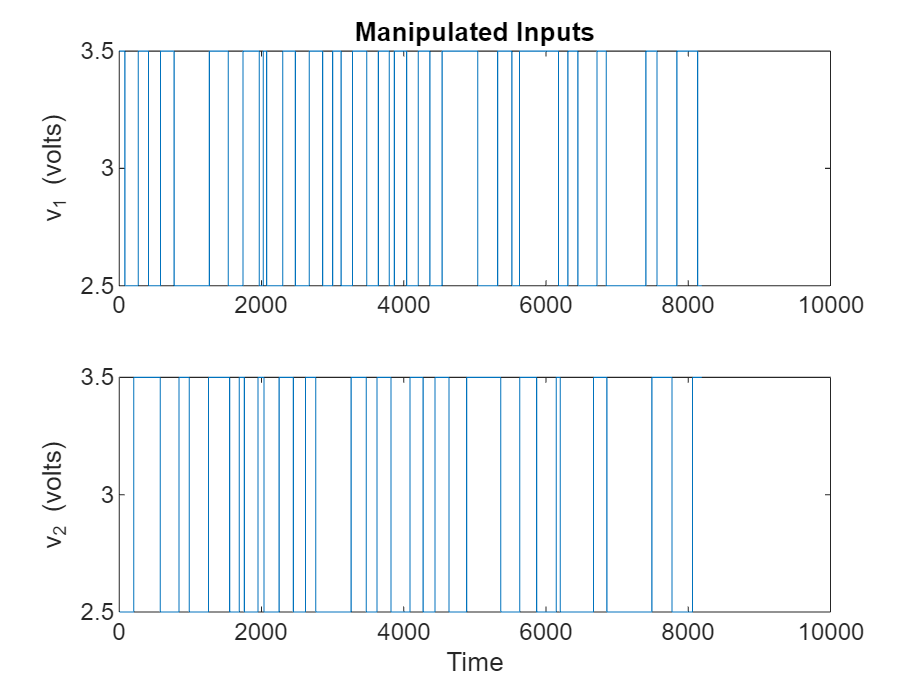

kT = zeros(1, N) ; % Array to record time 
for k = 1 : N-1
 k ;% Print sampling instant on screen;
 kT(k) = k * samp_T ; % update time array
 
 Uk(:,k) = uk(:,k) + QTank.Us ; % Manipulated input at instant k
 
 % Process Simulation from sampling instant k to (k+1)
 
 QTank.Uk = Uk(:,k) + wk(:,k) ;
 dk = QTank.dk_sigma * randn ;    % create Random fluctuations around Ds 
 QTank.Dk = QTank.Ds + dk ;      % Disturbance input  
 
 % Using MATLAB ODE Solver
 [T,Xt] =ode45( 'QTank_Dynamics', [ 0 samp_T ], Xk(:,k)) ;
 Xk(:,k+1) = Xt( end,: )' ; % Input noise case
 
 Yk(:,k+1) = QTank.C_mat * Xk(:,k+1) + vk(:,k+1) ;
 
 % Create output perturbation data for data driven modeling
 yk(:,k+1) = Yk(:,k+1) - QTank.Ys ;
end
% specify input at the final instant : 
 k = N ;
 kT(k) = k * samp_T ; 
 Uk(:,k)= QTank.Us + uk(:,k) ; 

 Set_Graphics_Parameters ;

figure(1)
subplot(211), stairs(kT, Uk(1,:), '-'), ylabel('v_1 (volts)'), title('Manipulated Inputs')
subplot(212), stairs(kT, Uk(2,:), '-'), ylabel('v_2 (volts)'), xlabel('Time')

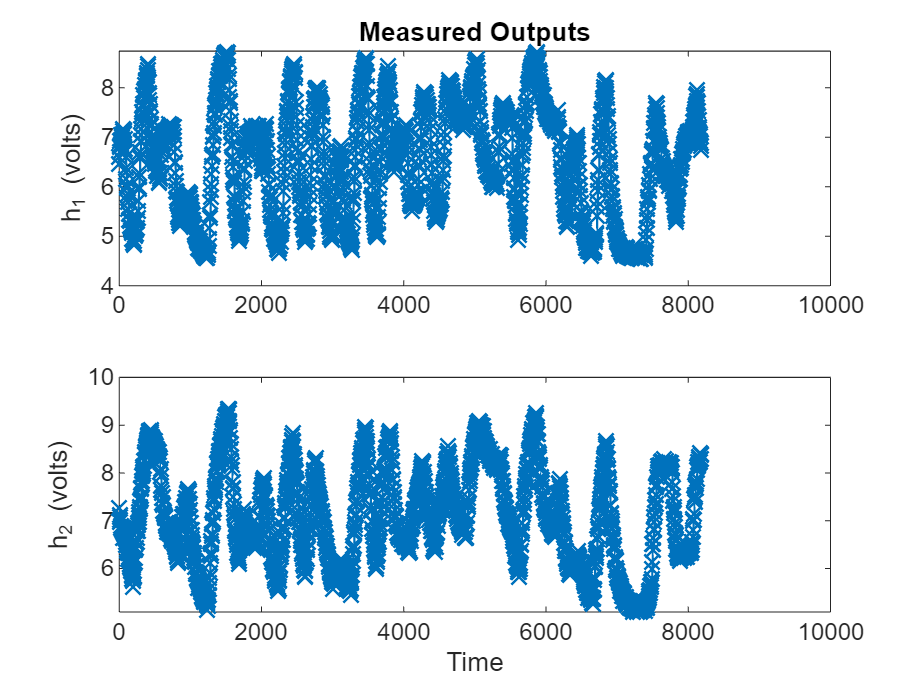

 figure(2)
subplot(211), plot(kT, Yk(1,:), '-x'), ylabel('h_1 (volts)'), title('Measured Outputs')
subplot(212), plot(kT, Yk(2,:), '-x'), ylabel('h_2 (volts)'), xlabel('Time')


Ys = QTank.Ys  ; Us = QTank.Us ; Ds = QTank.Ds ; Xs = QTank.Xs ;

if operating_pt==1
    save QTank_Expt_Data_MinPhase yk uk samp_T Xs Ys Us Ds kT
else
    save QTank_Expt_Data_NonMinPhase yk uk samp_T Xs Ys Us Ds kT
end

## Conclusion

In this lesson, we have studied how to generate experimental data needed for identification of control relevant data driven state space models using Quadruple Tank simulation. The data sets generated for the Q-Tank system will be used in the subsequent chapters for developing grey-box and black-box discrete time state space models. 

## References

-  HouWang : Z.-S. Hou and Z. Wang, "From model-based control to data-driven control: Survey, classification and perspective," Information Sciences, vol. 235, pp. 3--35, 2013

- Shumway, R. H., Stoffer, D. S. Time Series Analysis and Its Applications  

- Ljung, L., Glad, T., Modeling of Dynamic Systems, Prentice Hall, N. J., 1994.

- Ljung, L., System Identification: Theory for Users, Prentice Hall, 1987. 

- Soderstorm and Stoica, System Identification, 1989.

- Astrom, K. J., and B. Wittenmark, Computer Controlled Systems, Prentice Hall India (1994).

- Franklin, G. F., Powell, J. D., and M. L. Workman, Digital Control Systems, Addison Wesley, 1990.